# German Stocks - ANOVA

## 1.

Run the script `stocksDE3b.``mlx`. This creates a variable `index` containing historical returns of the German stock index DAX together with the corresponding month of the year information.

index = 890×1 table
                      DAX    
                   __________
    10-Jan-2007    -0.0072545
    11-Jan-2007       0.01822
    12-Jan-2007     0.0026687
    15-Jan-2007     0.0039548
    16-Jan-2007    -0.0022188
    17-Jan-2007    -0.0022536
    18-Jan-2007    -0.0018042
    19-Jan-2007     0.0085661
    22-Jan-2007    -0.0089115
    23-Jan-2007    -0.0012539
    24-Jan-2007      0.010343
    25-Jan-2007    -0.0042753
    26-Jan-2007     -0.004361
    29-Jan-2007     0.0053174
    30-Jan-2007     0.0092081
    31-Jan-2007    0.00012963

index = 890×2 table
                      DAX        Month
                   __________    _____
    10-Jan-2007    -0.0072545     Jan 
    11-Jan-2007       0.01822     Jan 
    12-Jan-2007     0.0026687     Jan 
    15-Jan-2007     0.0039548     Jan 
    16-Jan-2007    -0.0022188     Jan 
    17-Jan-2007    -0.0022536     Jan 
    18-Jan-2007    -0.0018042     Jan 
    19-Jan-2007     0.0085661     Jan 
    22-Jan-2007    -0.0089115     Jan 
    23-Jan-2007    -0.0012539     Jan 
    24-Jan-2007      0.010343     Jan 
    25-Jan-2007    -0.0042753     Jan 
    26-Jan-2007     -0.004361     Jan 
    29-Jan-2007     0.0053174     Jan 
    30-Jan-2007     0.0092081    

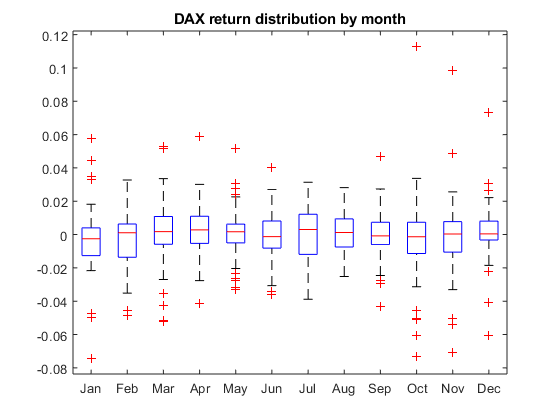

stocksDE3b

## 2.

Perform a 1-way ANOVA of DAX returns by month. Ask for at least the first and third output and turn off the table display.

[p,~,st] = anova1(index.DAX, index.Month, 'off');

## 3.

Display the resulting *p*-value (first output) at the command line. What is your conclusion?

disp(['p-value = ',num2str(p)])

p-value = 0.29011


## 4.

Visualize the results using the `multcompare` function.  Is this consistent with your conclusion from step 3?

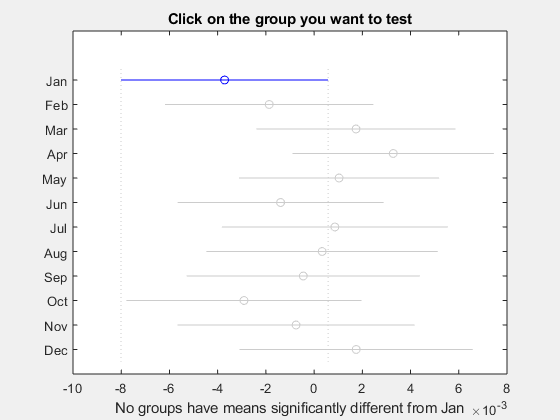

figure('Visible','on')
multcompare(st);